Definicja obiektu sterowania:

$G_{O}(s) = \frac{1}{s^2 + 2\xi\omega_{n}s + \omega_{n}^2}$.

Sterowanego regulatorem proporcjonalnym:

$G_{R}(s) = k_{p}$.

Ustaw tłumienie i drgania własne:

ksi =0.7;
omega_n = 1.31;

G = tf(1, [1, 2*ksi*omega_n, omega_n^2]);

Sprawdzamy dla jakich $k_p$układ zamkniety jest stabilny:

[r, krl] = rlocus(G, 0.1:0.1:10);

k = [];
for i = 1:length(krl)
    if all(real(r(:, i)) < 0)
        k = [k, krl(i)];
    end
end

Wyznaczamy przyblizone wartości dla różnych $k_p$:

- czas regulacji: $\tau_{r} = \frac{4}{\xi\omega_{n}}$,

- przeregulowanie: $\kappa = e^{-\frac{\pi\xi}{\sqrt{1 - \xi^2}}}$,

- czas pierwszego maksimum: $t_{p} = \frac{\pi}{\omega_{n}\sqrt{1 - \xi^2}}$.

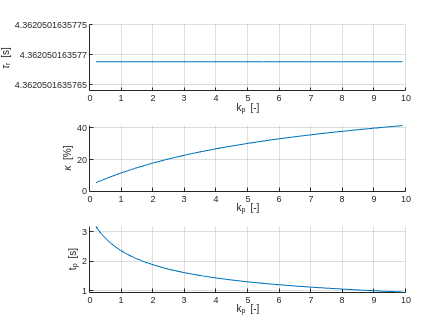

% Wyznaczenie dla różnych kp
ksi_k = zeros(length(krl)-2, 1);
omega_k = zeros(length(krl)-2, 1);

for i = 1:(length(krl)-2)
    kp = krl(i);
    Gz = feedback(kp*G, 1);
    den = Gz.Denominator{1};


    omega_k(i) = sqrt(den(3));
    ksi_k(i) = 0.5 * den(2) / sqrt(den(3));
end

tau_r = 4 ./ (ksi_k .* omega_k);
kappa = exp(-(pi*ksi_k)./(sqrt(1 - ksi_k.^2)));
tp = pi ./ (omega_k .* sqrt(1 - ksi_k.^2));

figure();

subplot(3, 1, 1);
grid on;
hold on;
xlabel("k_{p} [-]");
ylabel("\tau_{r} [s]");
plot(krl(2:end-1), tau_r)
subplot(3, 1, 2);
grid on;
hold on;
xlabel("k_{p} [-]");
ylabel("\kappa [%]");
plot(krl(2:end-1), 100*kappa);

subplot(3, 1, 3);
grid on;
hold on;
xlabel("k_{p} [-]");
ylabel("t_p [s]");
plot(krl(2:end-1), tp)

Wykreślenie odpowiedzi na skok jednostkowy:

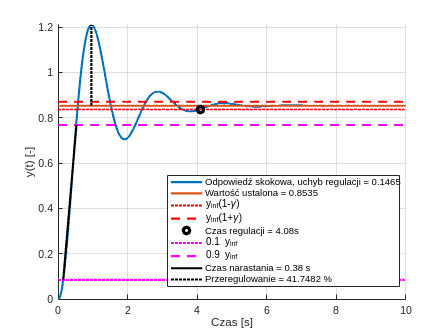

kp = 10;
Gz = feedback(kp*G, 1);

[y,t] = step(Gz, 0:0.01:10);

figure();
grid on;
hold on;
axis tight;
legend("show", "Location", "best");
xlabel("Czas [s]");
ylabel("y(t) [-]");

% Uchyb regulacji
y_inf = y(end);
e_inf = 1 - y_inf;
plot(t, y, "LineWidth", 2, "DisplayName", "Odpowiedź skokowa, uchyb regulacji = " + string(e_inf));
plot(t, ones(size(t))*y_inf, "LineWidth", 2, "DisplayName", "Wartość ustalona = " + string(y_inf));

% Cas regulacji
gamma = 0.02;
y_lower = y_inf * (1 - gamma);
y_upper = y_inf * (1 + gamma);
plot(t, ones(size(t))*y_lower, "r:", "LineWidth", 2, "DisplayName", "y_{inf}(1-\gamma)");
plot(t, ones(size(t))*y_upper, "r--", "LineWidth", 2, "DisplayName", "y_{inf}(1+\gamma)");
y_norm = (y - y_inf).^2;
t_reg = find(y_norm > (gamma * y_inf)^2, 1, "last");
plot(t(t_reg), y(t_reg), "ko", "LineWidth", 3, "DisplayName", "Czas regulacji = " + string(t(t_reg)) + "s");

% Czas narastania
t_rise_begin = find(y > (0.1 * y_inf), 1, "first");
t_rise_end = find(y > (0.9 * y_inf), 1, "first");
rise_time = t(t_rise_end) - t(t_rise_begin);

plot(t, ones(size(t))*(0.1 * y_inf), "m:", "LineWidth", 2, "DisplayName", "0.1 y_{inf}");
plot(t, ones(size(t))*(0.9 * y_inf), "m--", "LineWidth", 2, "DisplayName", "0.9 y_{inf}");
plot([t(t_rise_begin), t(t_rise_end)], [(0.1 * y_inf), (0.9 * y_inf)], "k", "LineWidth", 2, "DisplayName", "Czas narastania = " + string(rise_time) + " s");

% Przeregulowanie
[y_max, index_max] = max(y);
kappa = 100 * (y_max - y_inf) / y_inf;

plot([t(index_max), t(index_max)], [y_inf, y_max], "k:", "LineWidth", 2, "DisplayName", "Przeregulowanie = " + string(kappa) + " %");